%bikes = [3, 3, 1, 1, 2, 3, 3, 4];
%t = [{'00:10'}, {'00:30'}, {'00:40'}, {'01:00'}, {'01:20'}, {'01:50'}, {'02:40'}, {'04:50'}];
%[t, bikes] = textread('freqs.csv', '%5s %f', 'delimiter', ',')
a = textscan(fopen("freqs.csv"), '%s %d', 'Delimiter',',');
t = a{1};
bikes = a{2};
if size(bikes) ~= size(t)
    disp('oh snap, invalid sizes')
end

Accumulate count of bikes

total = sum(bikes);
disp(strcat('In total, ', string(total), ...
    ' bikes passed during 30 minutes'))

In total,78 bikes passed during 30 minutes


disp(strcat('That means 𝜆=', string(total / 30), ...
    ' bikes pass on average every minute'))

That means 𝜆=2.6 bikes pass on average every minute


bikes = cumsum(bikes);

Convert to time

dt = datetime(t, 'Format','mm:ss');

Plot

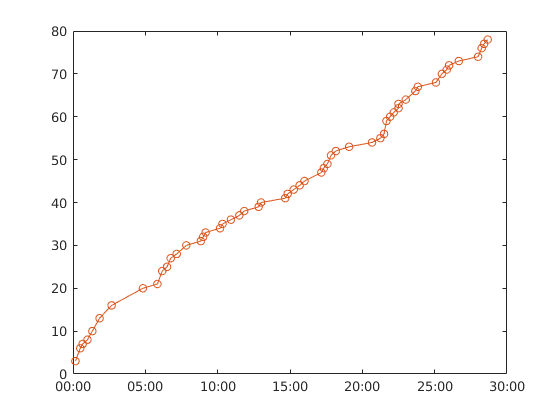

plot(datenum(dt), bikes, '-o')
hold on;
datetick('x', 'MM:SS')